# Lab 4 - Prediction

## Init

clear;

## R1.a)

Least squares estimate of linear model:


$$y := [x(N+1)\;x(N+2)\;...\;x(T)]^T$$



$$H := [x(1)\;x(2)\;...\;x(T-N)]^T$$



$$\theta = a$$



$$\hat{a} = (H^T H)^{-1}H^T y$$


## R1.b)

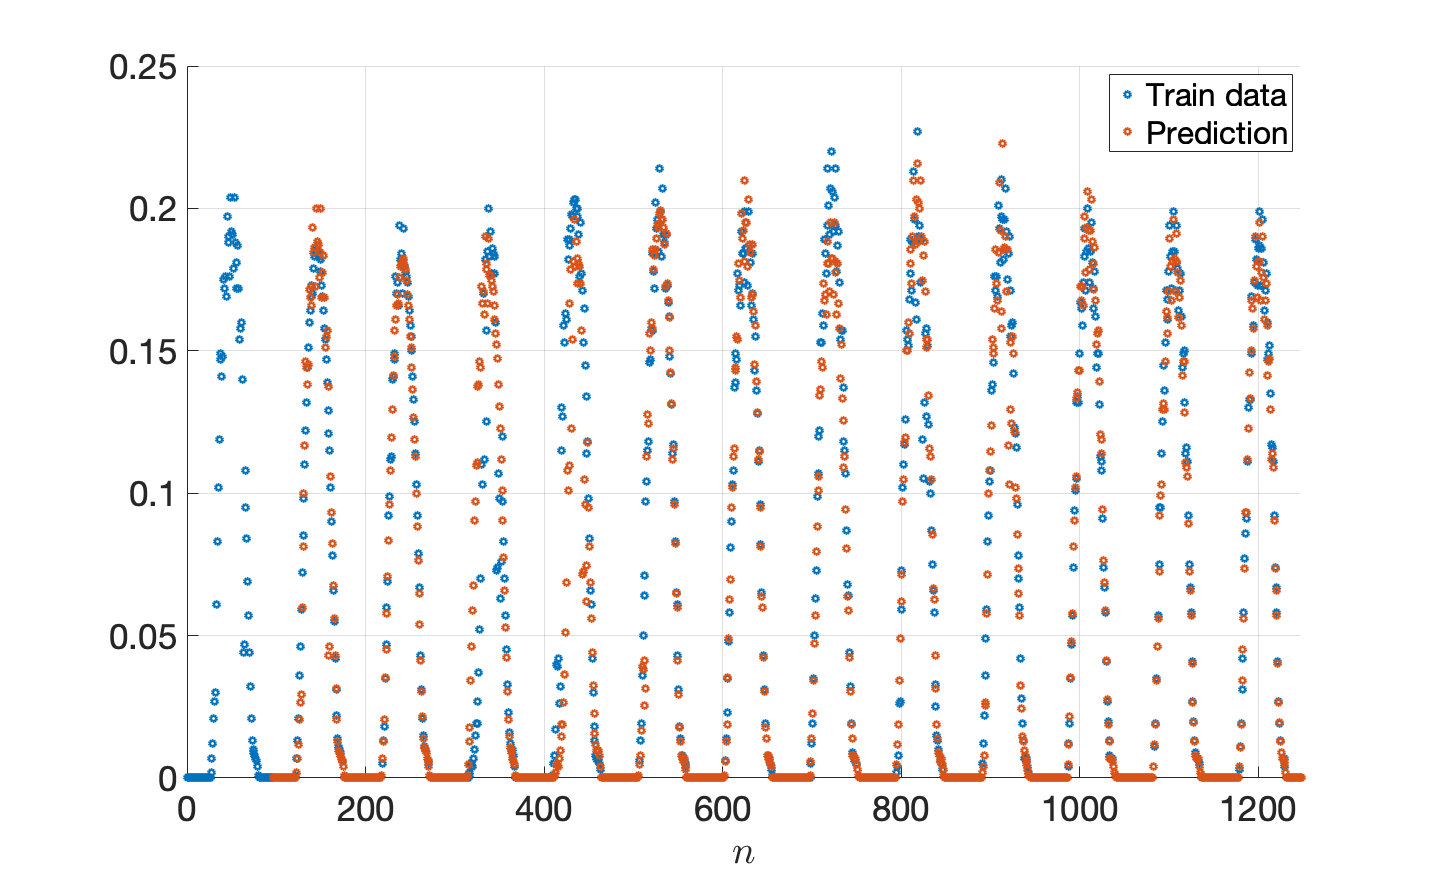

load("energy_train.mat",'x_train');
N = 96;
[a_hat_x,E] = ARmodelR1a(x_train,N);
x_pred = zeros(length(x_train),1);
for i = N+1:length(x_pred)
    x_pred(i) = x_train(i-N)*a_hat_x;
end
if true
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(1:length(x_train),x_train,'LineWidth',3);
scatter(N+1:length(x_train),x_pred(N+1:end),'LineWidth',3);
xlim([0 length(x_train)]);
legend("Train data","Prediction");
saveas(gcf,'./figures/R1b_train.png');
end

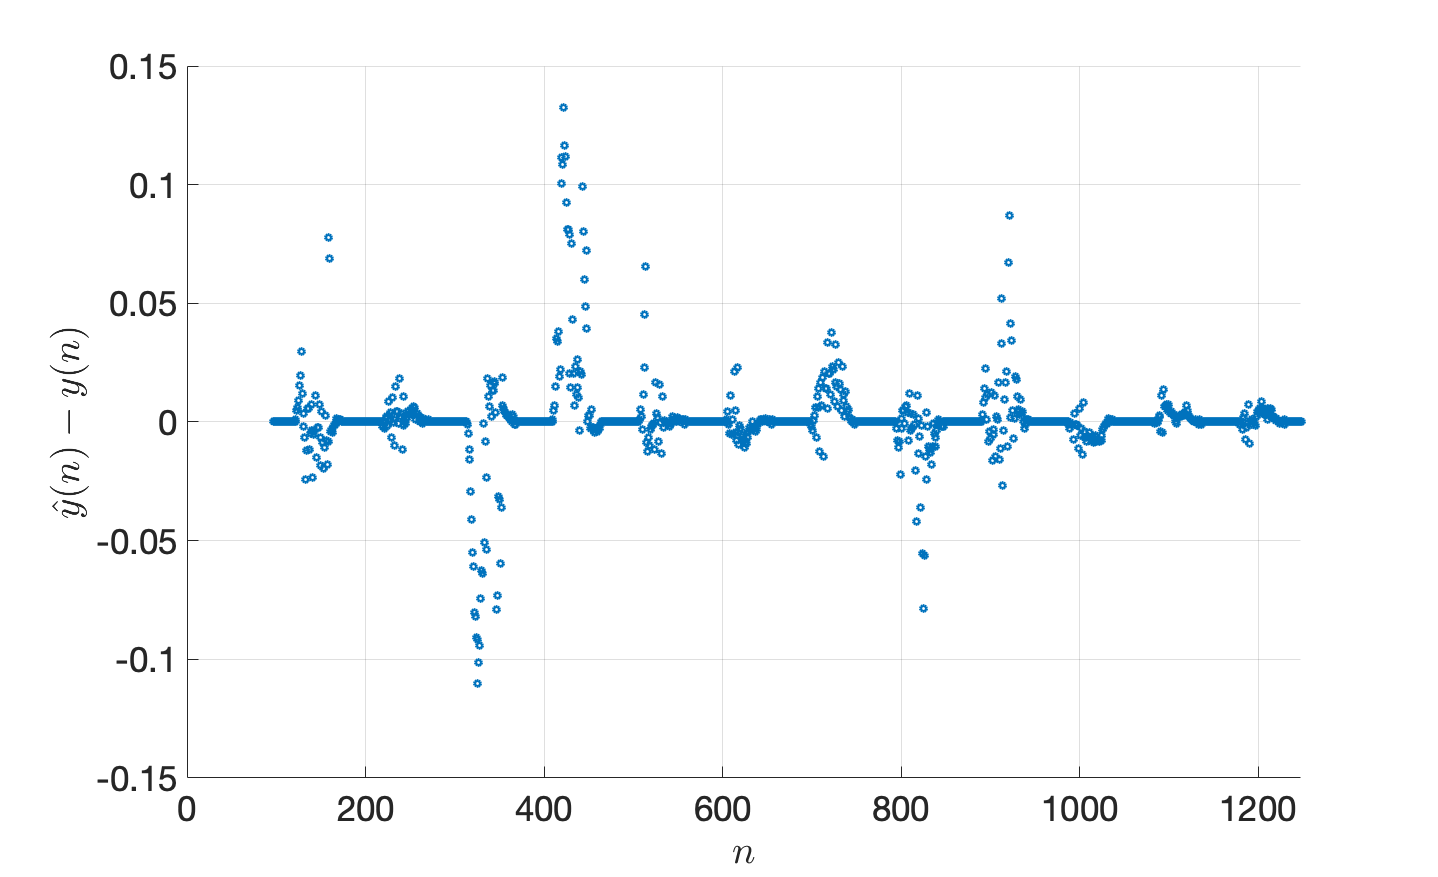

% Compute residual
r_train = x_train(N+1:end)-x_pred(N+1:end);
if true
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
ylabel("$\hat{y}(n)-y(n)$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+1:length(x_train),r_train,'LineWidth',3);
xlim([0 length(x_train)]);
saveas(gcf,'./figures/R1b_error.png');
end

## R1.c)

a_hat_x

a_hat_x = 0.9810

E

E = 0.3478

## R1.d)

Least squares estimate of linear model:


$$P<N$$



$$y:= [r(N+P+1)\;...\;r(T)]^T$$



$$H := [x(N+P)\;...\;x(N+1)\\\quad \quad \;\;\; x(N+P+1)\;...\; x(N+2)\\ \quad \quad \;\;\; ...\\\quad \quad \;\;\; x(T-1)\;...\;x(T-P)]$$



$$\theta =  [a_1\;a_2\;...\;a_P]^T$$



$$\hat{a} = (H^T H)^{-1}H^T y$$


## R1.e)

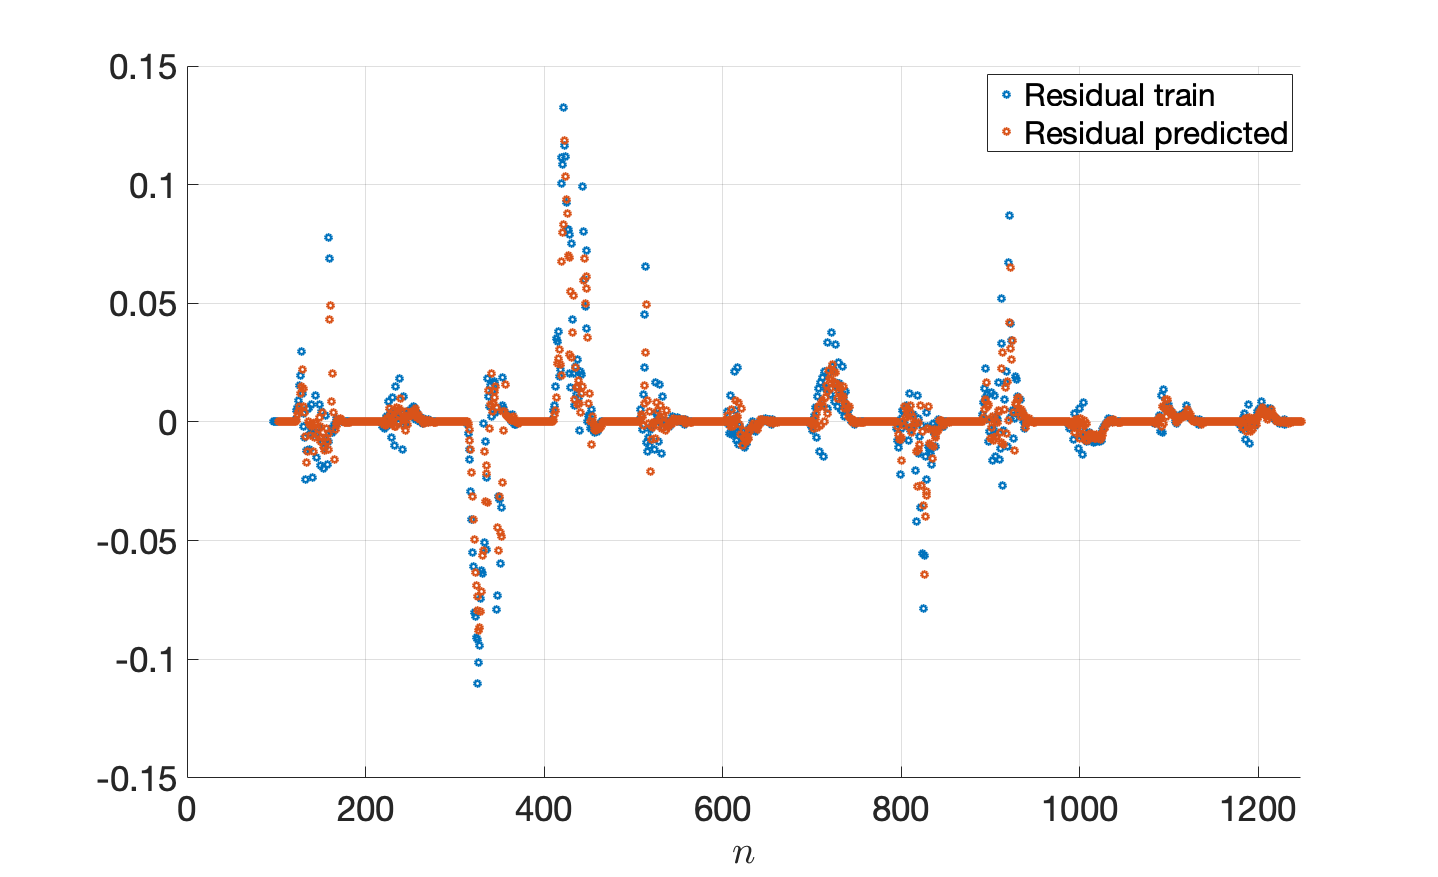

P = 6;
[a_hat_r,E] = ARmodelR1d(r_train,P);

r_pred = zeros(length(r_train),1);
for i = P+1:length(r_pred)
    for p = 1:P
        r_pred(i) = r_pred(i) + a_hat_r(p)*r_train(i-p);
    end
end

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+1:length(x_train),r_train,'LineWidth',3);
scatter(N+P+1:length(x_train),r_pred(P+1:end),'LineWidth',3);
xlim([0 length(x_train)]);
legend("Residual train","Residual predicted");
saveas(gcf,'./figures/R1e_residual.png');

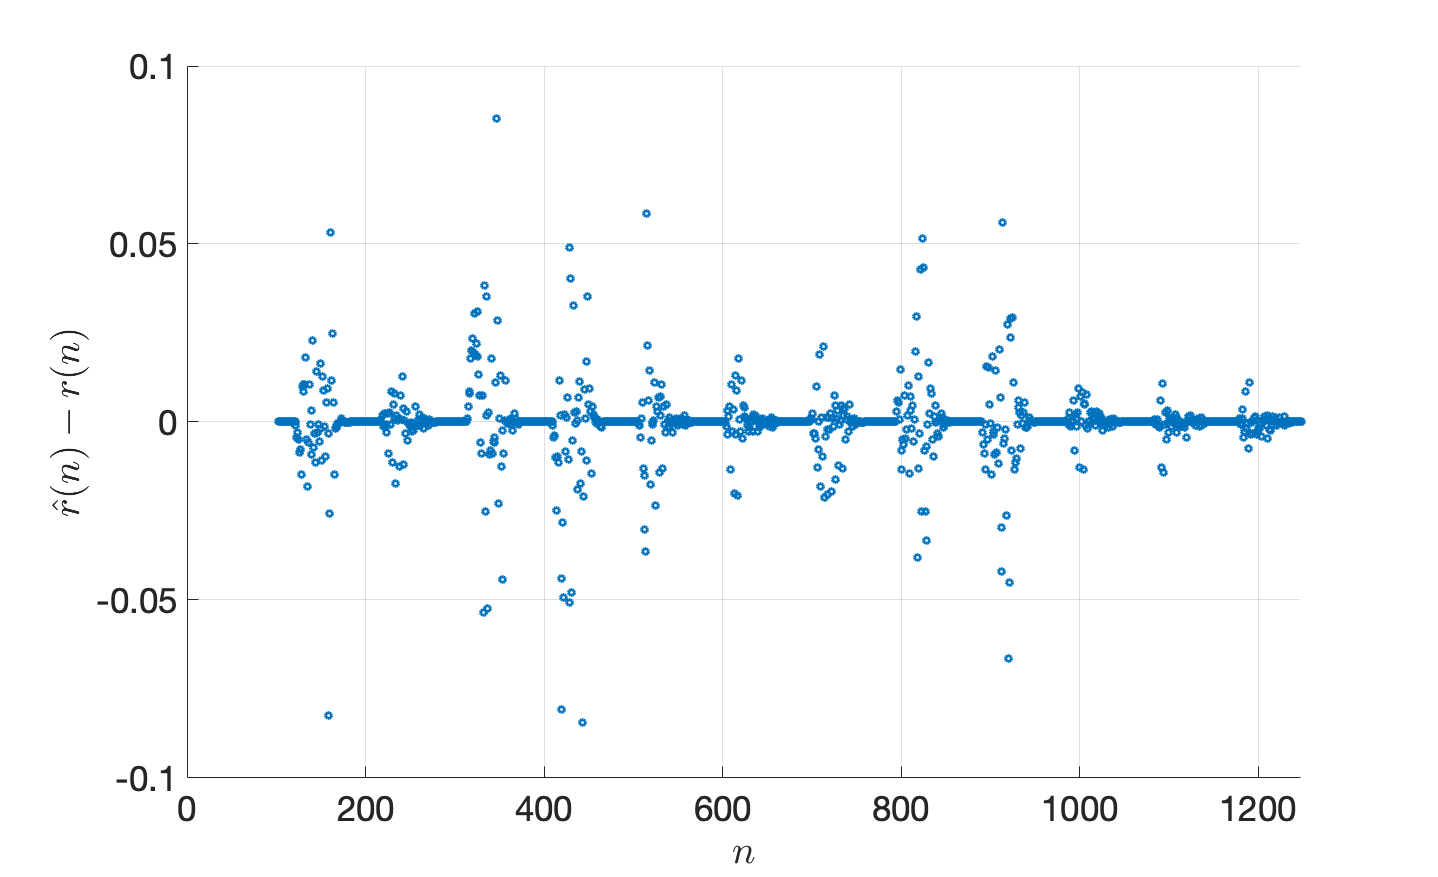

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
ylabel("$\hat{r}(n)-r(n)$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+P+1:length(x_train),r_pred(P+1:end)-r_train(P+1:end),'LineWidth',3);
xlim([0 length(x_train)]);
saveas(gcf,'./figures/R1e_error.png');

## R1.f

a_hat_r

a_hat_r =     0.5993
    0.1496
   -0.0031
    0.2730
   -0.1552
   -0.0279


E

E = 0.1248

## R2.a)

threshold = 0.1;

## R2.b)

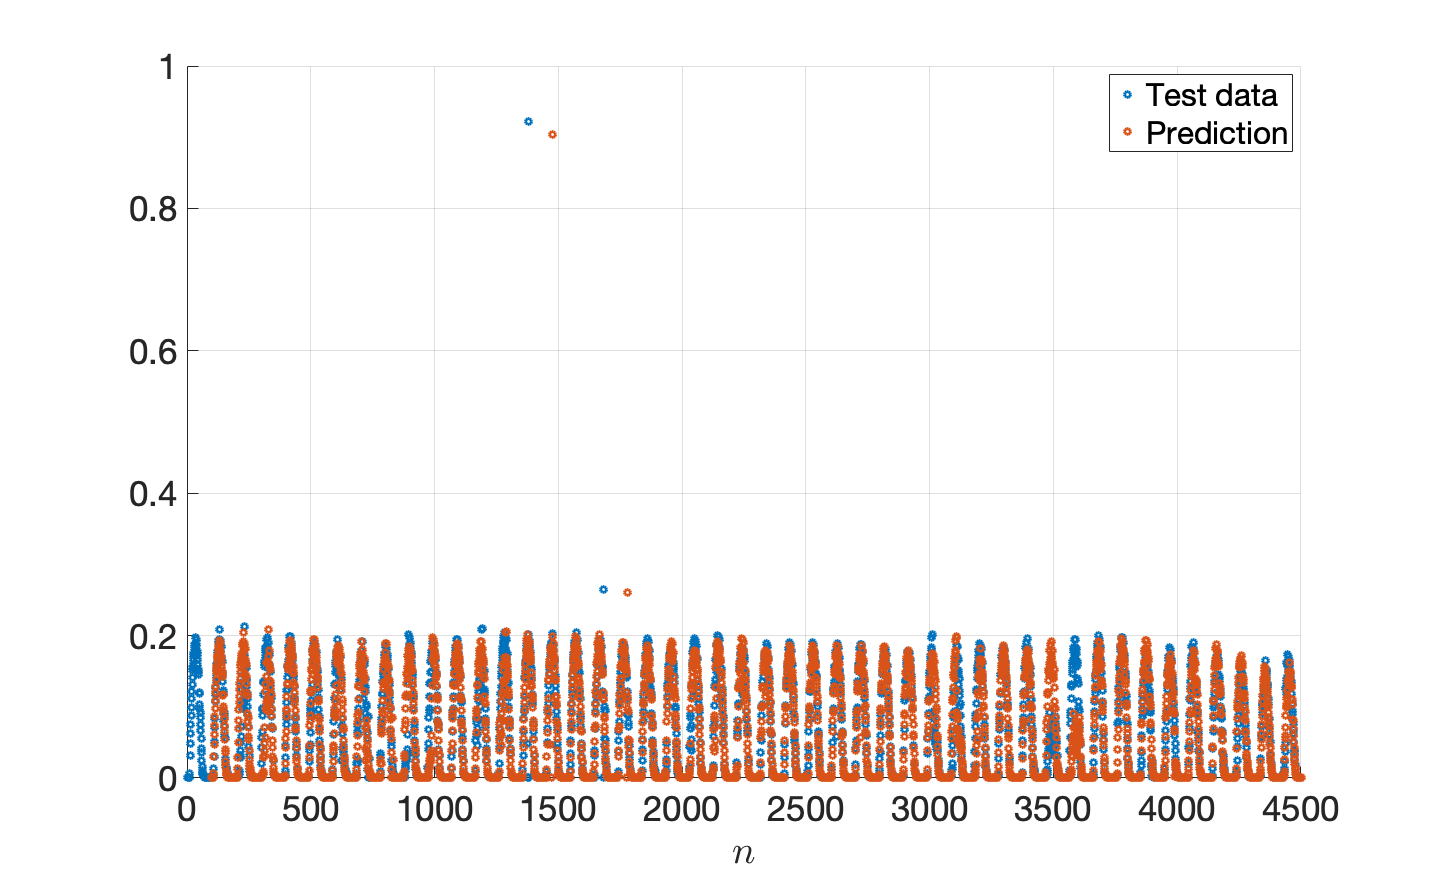

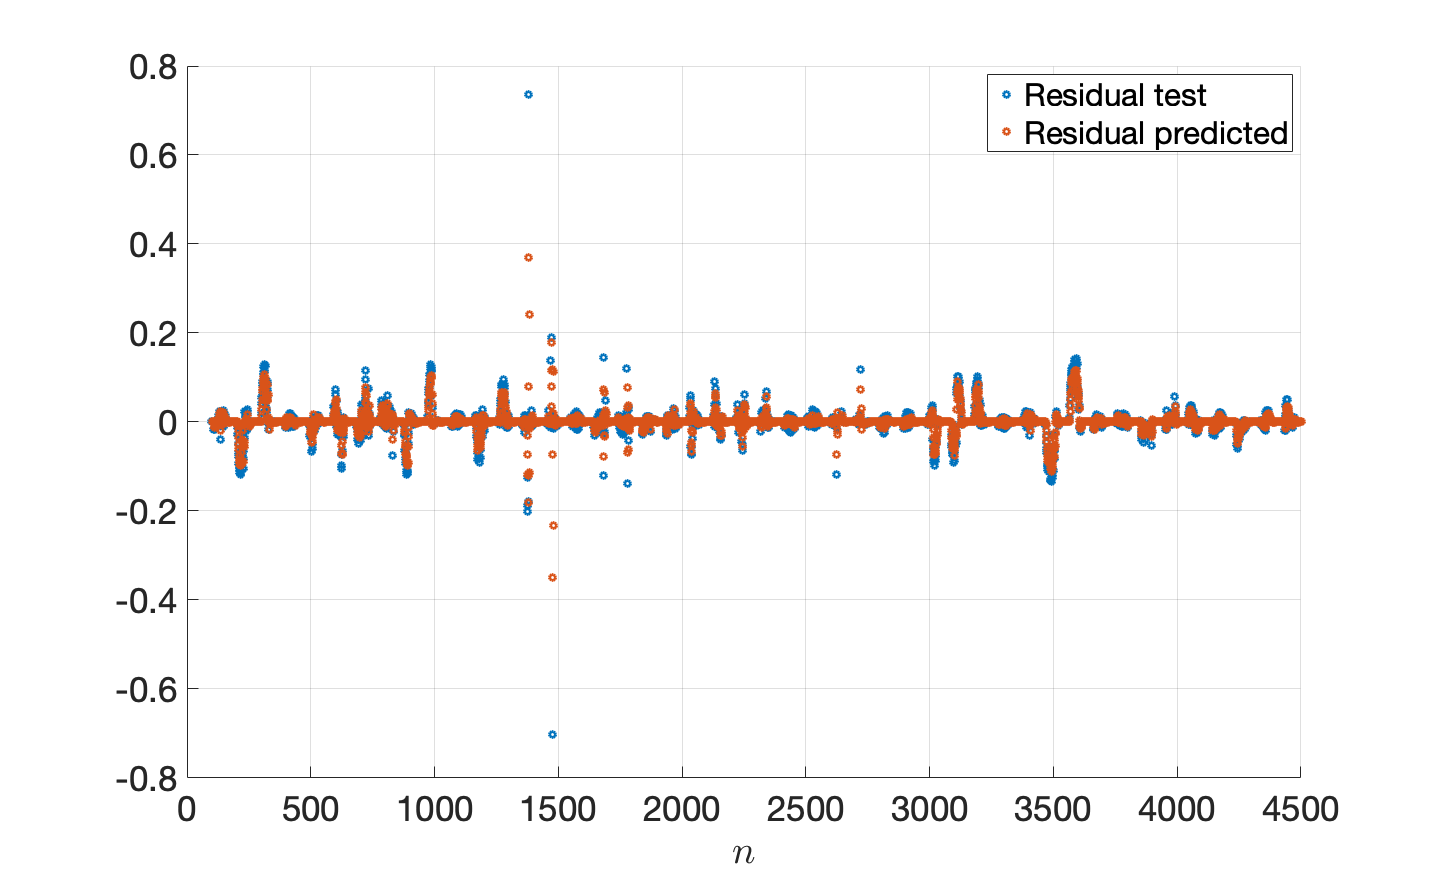

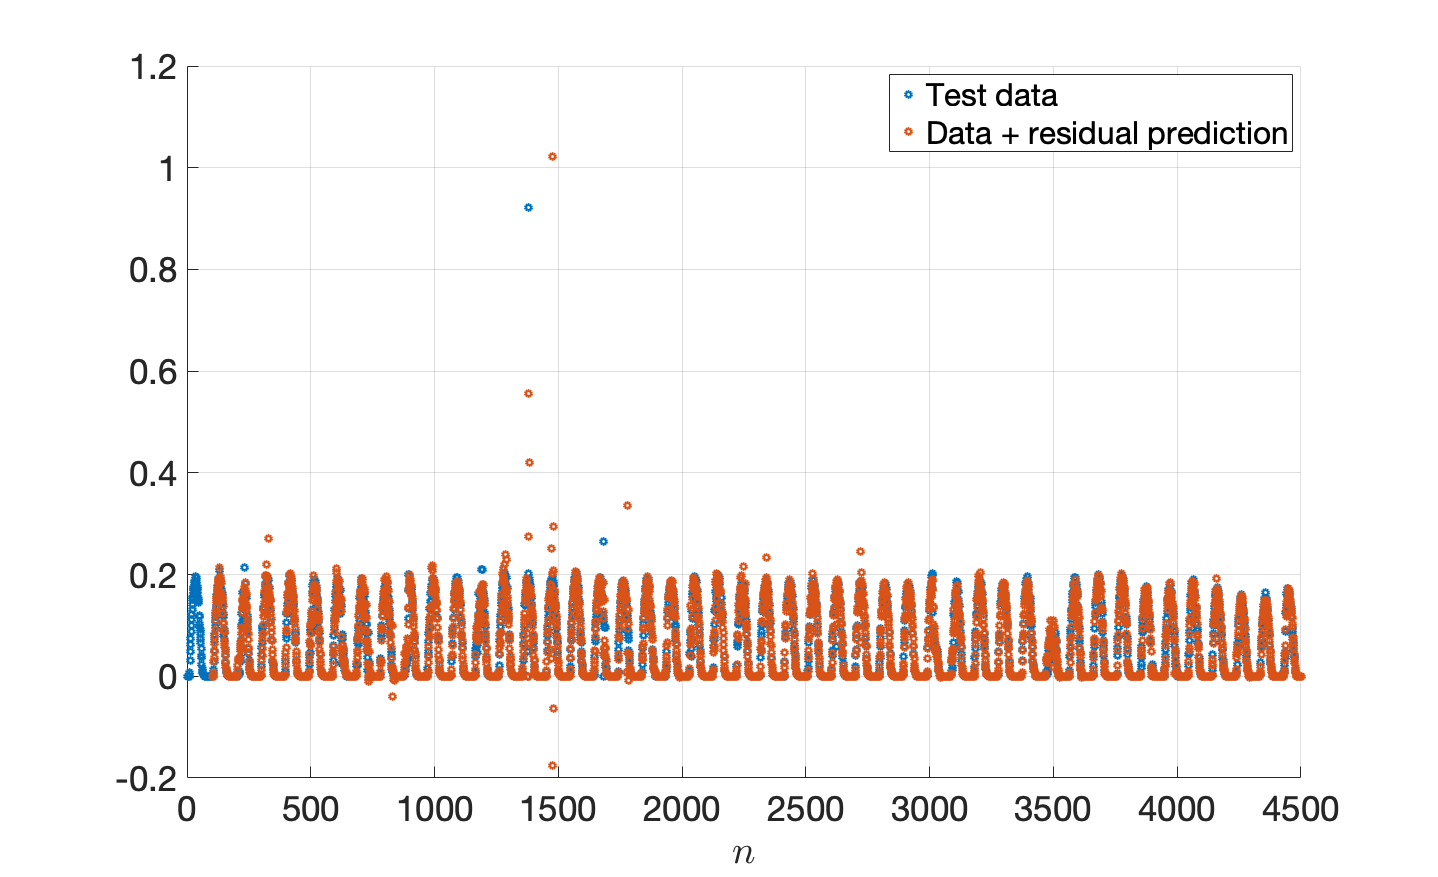

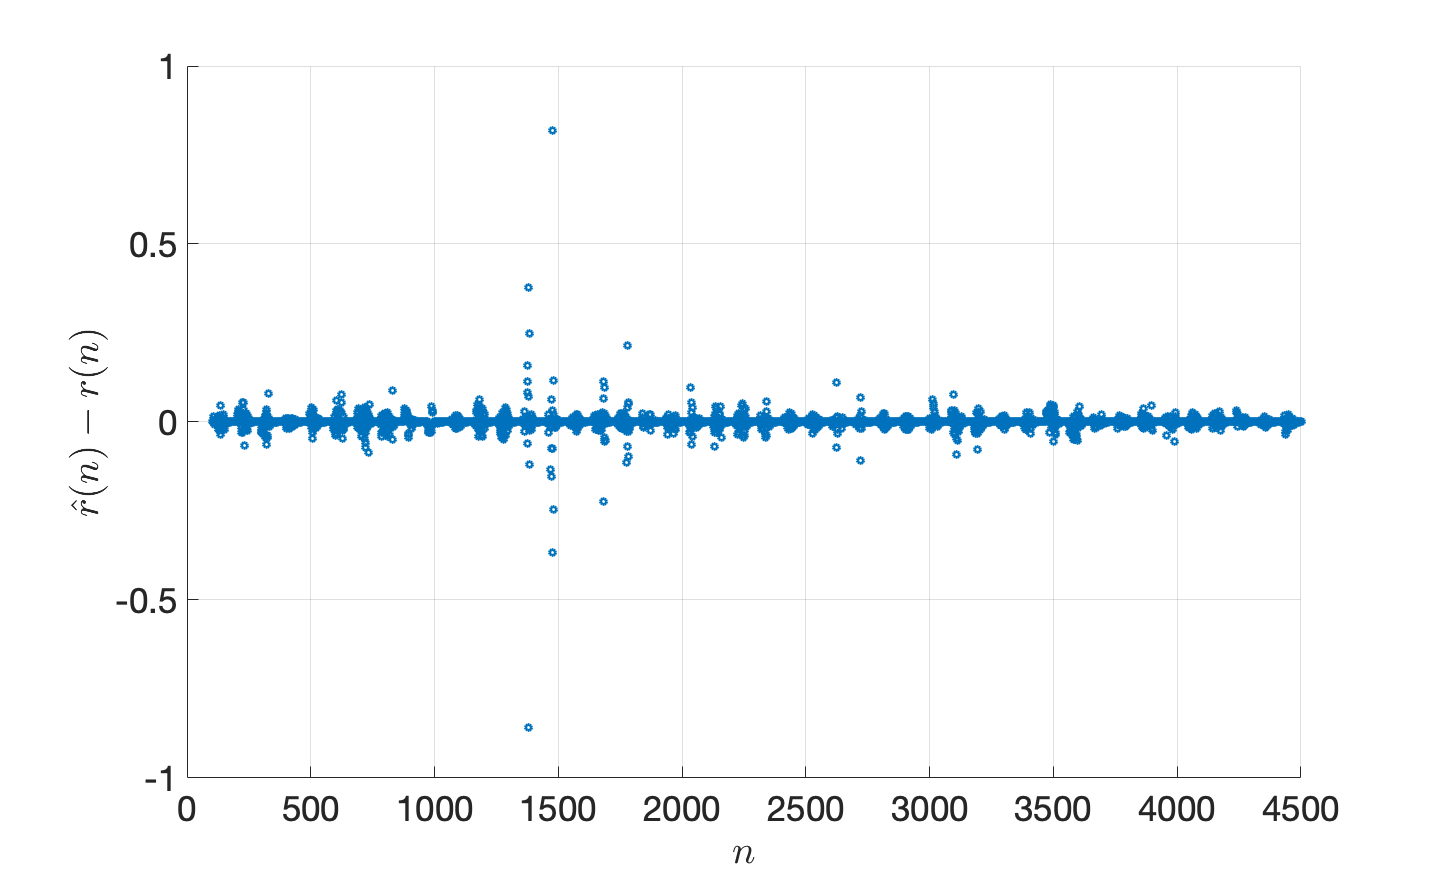

load("energy_test.mat",'x_test');

x_pred = zeros(length(x_test),1);
for i = N+1:length(x_test)
    x_pred(i) = x_test(i-N)*a_hat_x;
end
r_test = x_test(N+1:end)-x_pred(N+1:end);
r_pred = zeros(length(r_test),1);
for i = P+1:length(r_pred)
    for p = 1:P
        r_pred(i) = r_pred(i) + a_hat_r(p)*r_test(i-p);
    end
end
if true
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(1:length(x_test),x_test,'LineWidth',3);
scatter(N+1:length(x_test),x_pred(N+1:end),'LineWidth',3);
xlim([0 length(x_test)]);
legend("Test data","Prediction");
saveas(gcf,'./figures/R2b_test.png');

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+1:length(x_test),r_test,'LineWidth',3);
scatter(N+P+1:length(x_test),r_pred(P+1:end),'LineWidth',3);
xlim([0 length(x_test)]);
legend("Residual test","Residual predicted");
saveas(gcf,'./figures/R2b_residual.png');

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(1:length(x_test),x_test,'LineWidth',3);
scatter(N+P+1:length(x_test),x_pred(N+P+1:end)+r_pred(P+1:end),'LineWidth',3);
xlim([0 length(x_test)]);
legend("Test data","Data + residual prediction");
saveas(gcf,'./figures/R2b_data_residual.png');
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
ylabel("$\hat{r}(n)-r(n)$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+P+1:length(x_test),r_pred(P+1:end)-r_test(P+1:end),'LineWidth',3);
xlim([0 length(x_test)]);
saveas(gcf,'./figures/R2b_error.png');
end

## Dectect anomalous periods

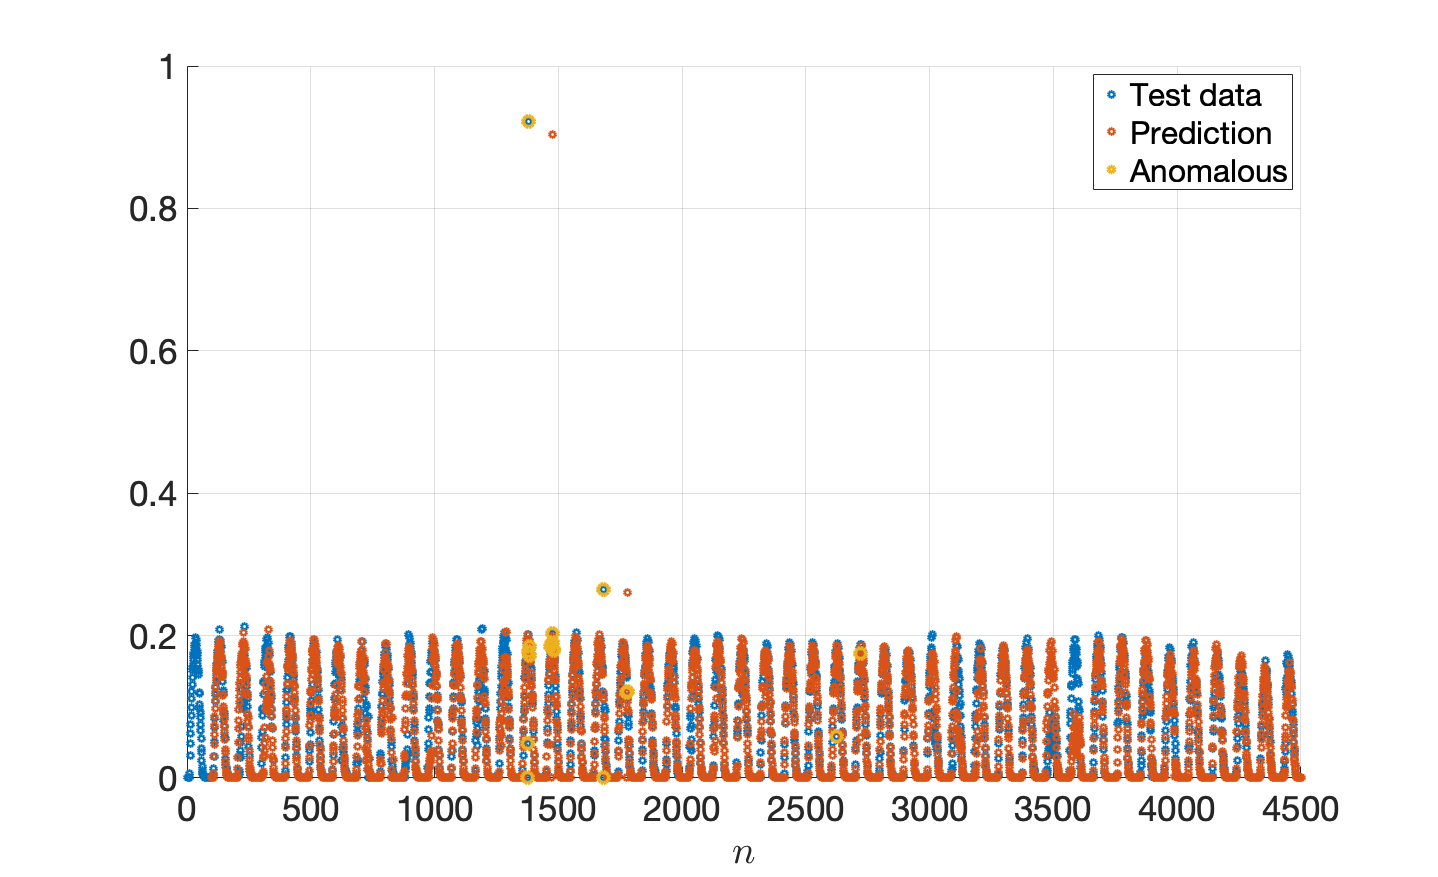

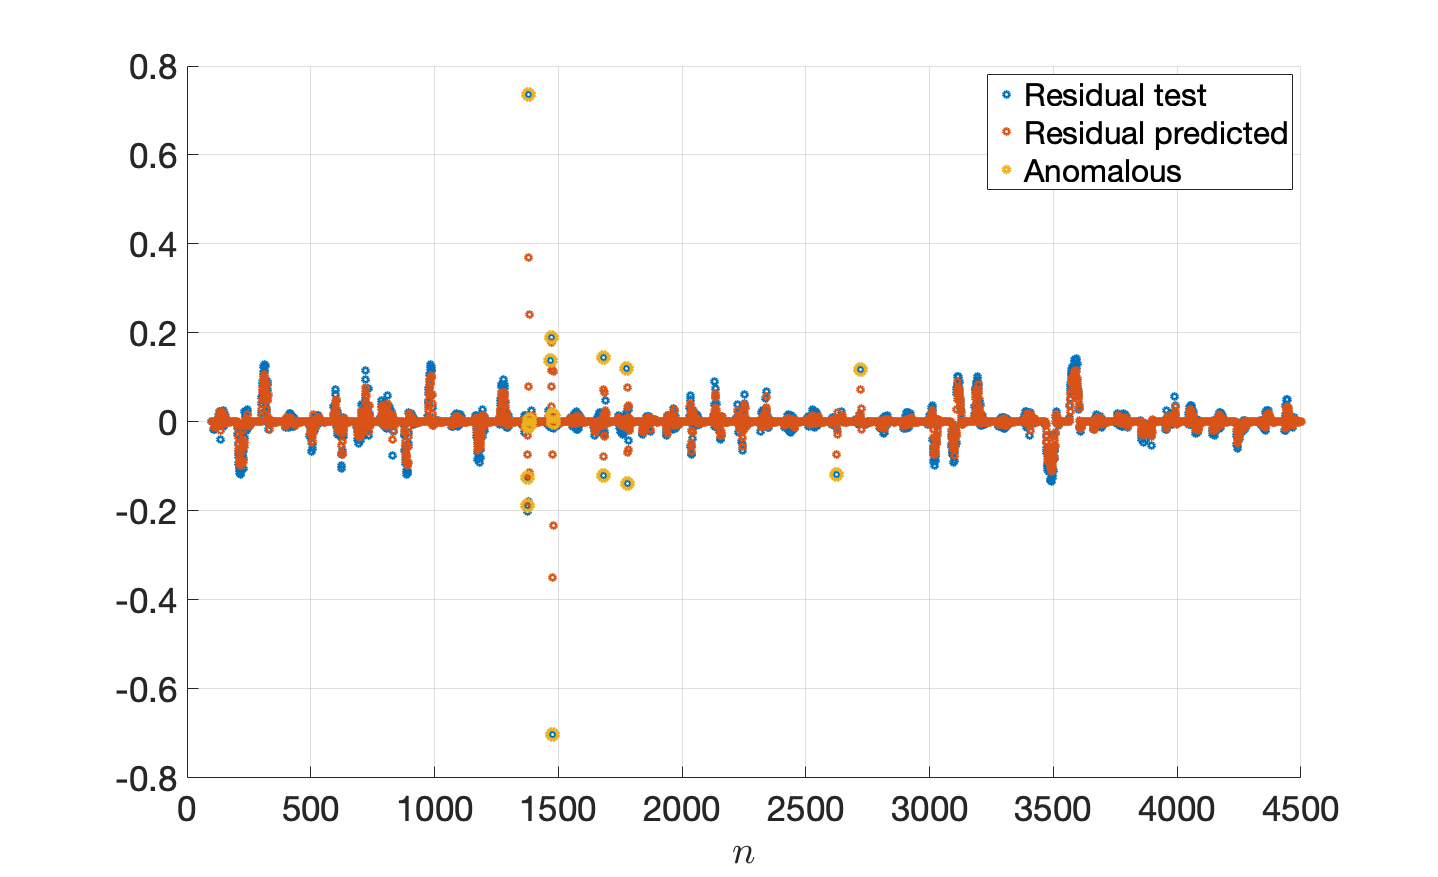

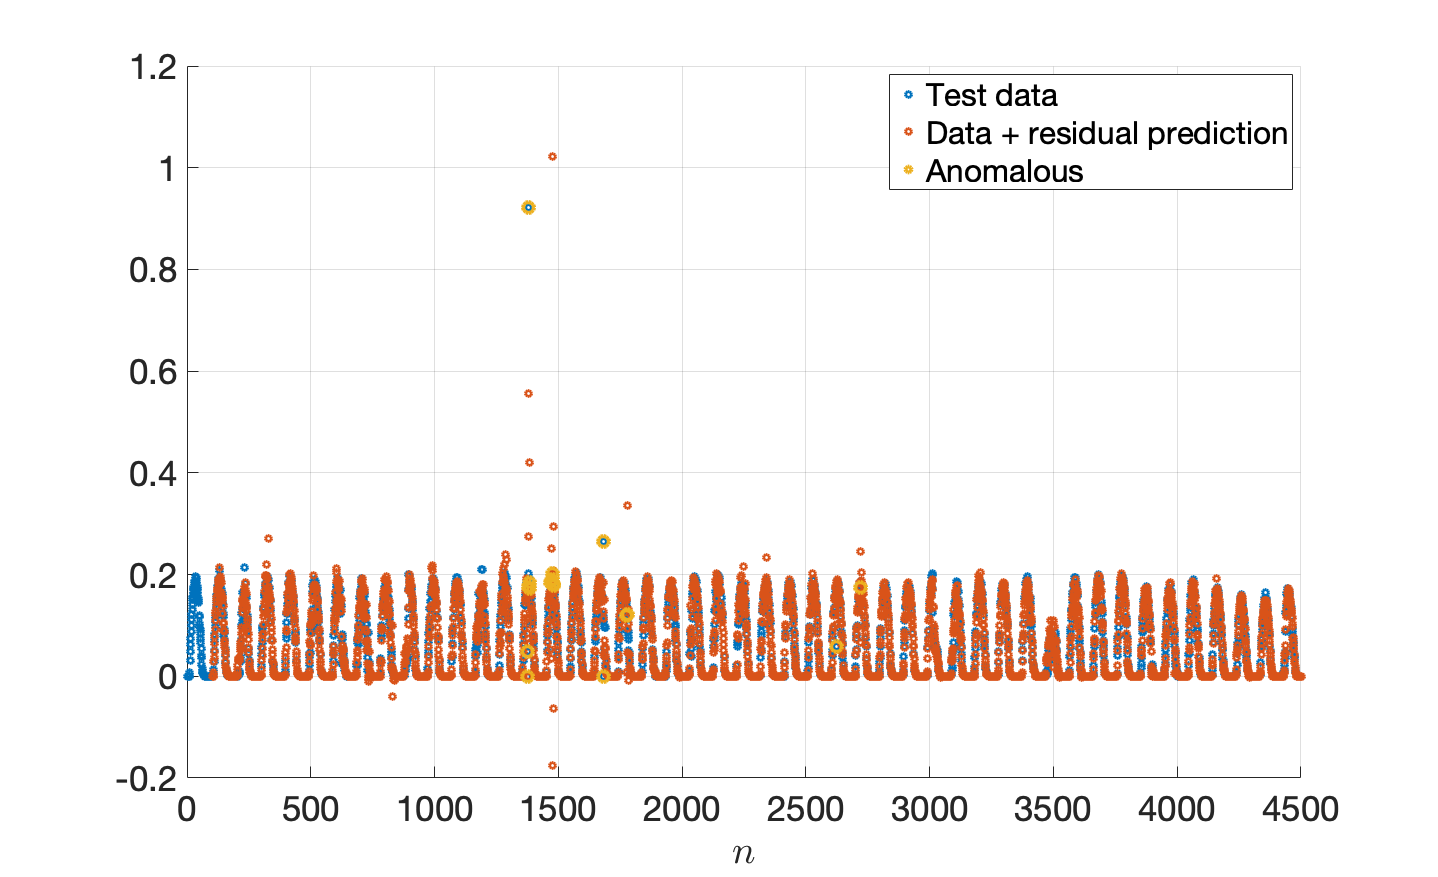

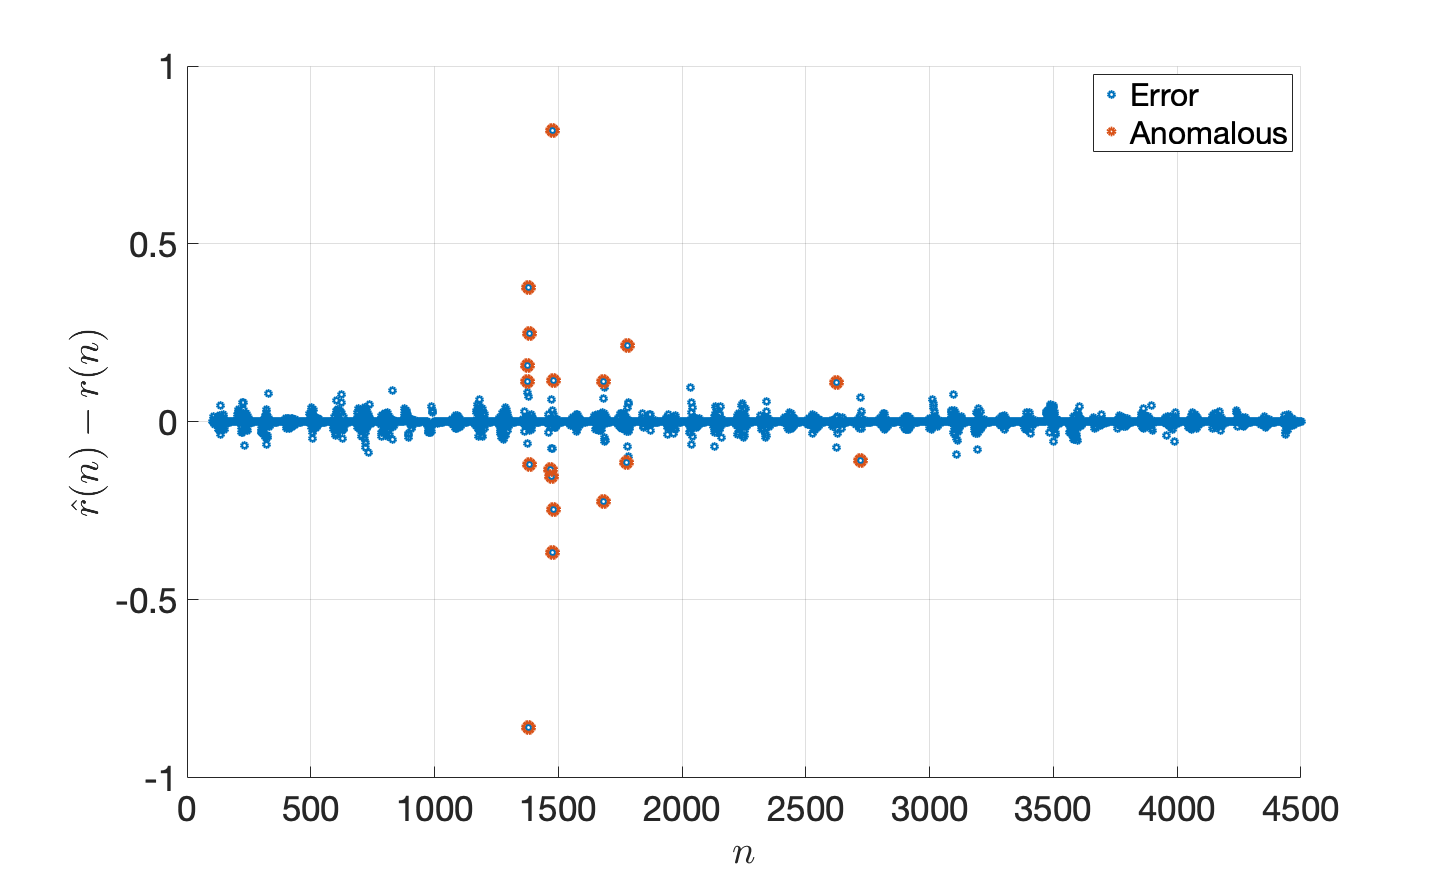

anomaly = anomalyR2a(r_test(P+1:end),r_pred(P+1:end),threshold);

n_an = (P+1:length(r_test))';
n_an = n_an(anomaly==1);
x_test_an = x_test(N+P+1:end);
x_test_an = x_test_an(anomaly==1);
r_test_an = r_test(P+1:length(r_test));
r_test_an = r_test_an(anomaly==1);
x_test_res_an = x_test(N+P+1:end);
x_test_res_an = x_test_res_an(anomaly==1);
e_an = x_pred(N+P+1:end)+r_pred(P+1:end)-x_test(N+P+1:end);
e_an = e_an(anomaly==1);

if true
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(1:length(x_test),x_test,'LineWidth',3);
scatter(N+1:length(x_test),x_pred(N+1:end),'LineWidth',3);
scatter(N+n_an,x_test_an,120,'LineWidth',4)
xlim([0 length(x_test)]);
legend("Test data","Prediction","Anomalous");
saveas(gcf,'./figures/R2c_test.png');
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+1:length(x_test),r_test,'LineWidth',3);
scatter(N+P+1:length(x_test),r_pred(P+1:end),'LineWidth',3);
scatter(N+n_an,r_test_an,120,'LineWidth',4)
xlim([0 length(x_test)]);
legend("Residual test","Residual predicted","Anomalous");
saveas(gcf,'./figures/R2c_residual.png');

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(1:length(x_test),x_test,'LineWidth',3);
scatter(N+P+1:length(x_test),x_pred(N+P+1:end)+r_pred(P+1:end),'LineWidth',3);
scatter(N+n_an,x_test_res_an,120,'LineWidth',4)
xlim([0 length(x_test)]);
legend("Test data","Data + residual prediction","Anomalous");
saveas(gcf,'./figures/R2c_data_residual.png');
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
ylabel("$\hat{r}(n)-r(n)$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+P+1:length(x_test),r_pred(P+1:end)-r_test(P+1:end),'LineWidth',3);
scatter(N+n_an,e_an,120,'LineWidth',4)
xlim([0 length(x_test)]);
legend("Error","Anomalous");
saveas(gcf,'./figures/R2c_error.png');
end

## R2.c) Correct anomalies of the first period

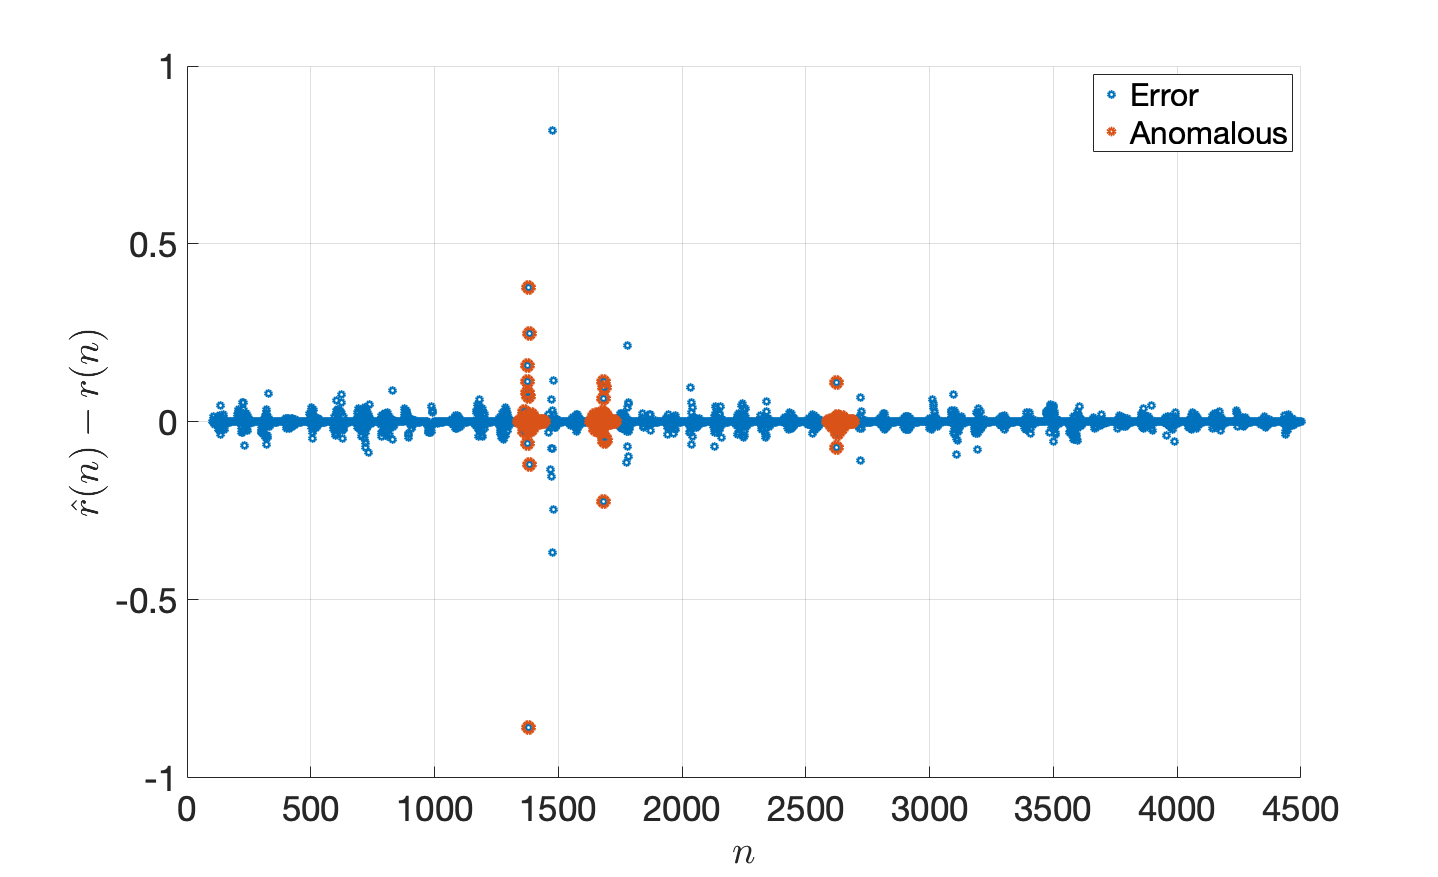

anomaly_cor = anomaly;
i = N+P+1;
while i<= length(x_test)
    if anomaly_cor(i-N-P)==1
        n = floor(i/N);
        for j = N*(n)+1:N*(n+1)
            if j > length(x_test)
                break;
            end
            anomaly_cor(j-P-N) = 1;
        end
        for j = N*(n+1)+1:N*(n+2)
            if j > length(x_test)
                break;
            end
            anomaly_cor(j-P-N) = 0;
        end
        i = N*(n+2);
    else
        i = i+1;
    end
    
end

n_an_cor = (P+1:length(r_test))';
n_an_cor = n_an_cor(anomaly_cor==1);
e_an_cor = x_pred(N+P+1:end)+r_pred(P+1:end)-x_test(N+P+1:end);
e_an_cor = e_an_cor(anomaly_cor==1);
figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
ylabel("$\hat{r}(n)-r(n)$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+P+1:length(x_test),r_pred(P+1:end)-r_test(P+1:end),'LineWidth',3);
scatter(N+n_an_cor,e_an_cor,120,'LineWidth',4)
xlim([0 length(x_test)]);
legend("Error","Anomalous");
saveas(gcf,'./figures/R2d_error.png');

% Correct anomalies
x_test_cor = x_test;
x_test_cor([zeros(N,1);anomaly_cor] == 1) = x_pred([zeros(N,1);anomaly_cor] == 1)+r_pred([zeros(N,1);anomaly_cor] == 1);
% Predict
x_pred_cor = zeros(length(x_test_cor),1);
for outter = 1:20
    for i = N+1:length(x_test_cor)
        x_pred_cor(i) = x_test_cor(i-N)*a_hat_x;
    end
    r_test_cor = x_test_cor(N+1:end)-x_pred_cor(N+1:end);
    r_pred_cor = zeros(length(r_test_cor),1);
    for i = P+1:length(r_pred_cor)
        for p = 1:P
            r_pred_cor(i) = r_pred_cor(i) + a_hat_r(p)*r_test_cor(i-p);
        end
    end
    x_test_cor([zeros(N,1);anomaly_cor] == 1) = x_pred_cor([zeros(N,1);anomaly_cor] == 1)+r_pred_cor([zeros(N,1);anomaly_cor] == 1);
end
x_cor = x_pred_cor(N+P+1:end)+r_pred_cor(P+1:end);
e_cor = x_cor-x_test(N+P+1:end);

## PLot

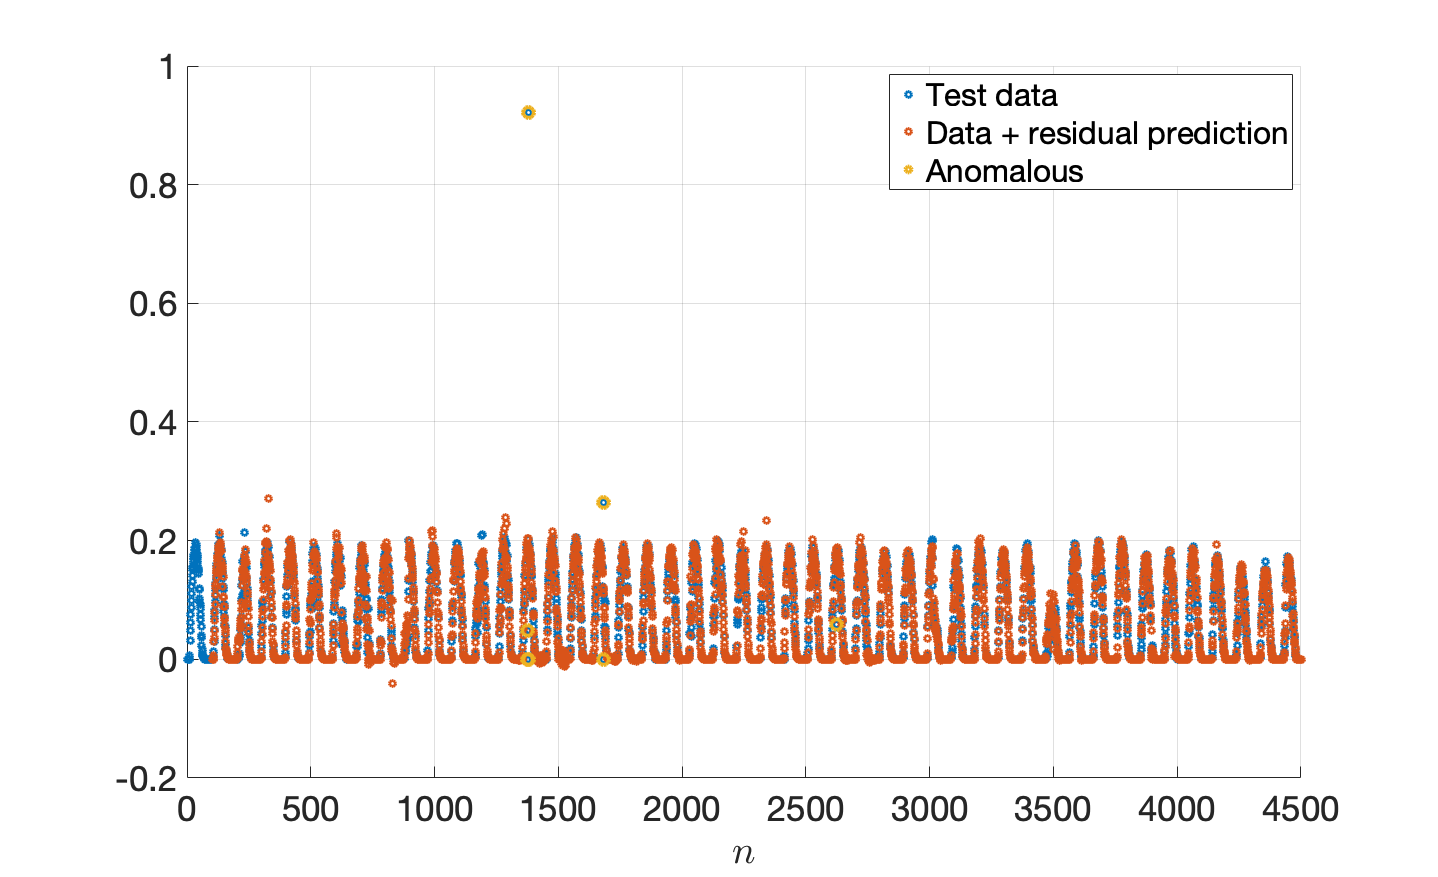

anomaly = anomalyR2a(e_cor,zeros(length(e_cor),1),threshold);

n_an = (P+1:length(r_test))';
n_an = n_an(anomaly==1);
x_test_an = x_test(N+P+1:end);
x_test_an = x_test_an(anomaly==1);
e_an = x_pred_cor(N+P+1:end)+r_pred_cor(P+1:end)-x_test(N+P+1:end);
e_an = e_an(anomaly==1);



figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(1:length(x_test),x_test,'LineWidth',3);
scatter(N+P+1:length(x_test),x_cor(1:end),'LineWidth',3);
scatter(N+n_an,x_test_an,120,'LineWidth',4)
xlim([0 length(x_test)]);
legend("Test data","Data + residual prediction","Anomalous");
saveas(gcf,'./figures/R2d_data_residual.png');

## p

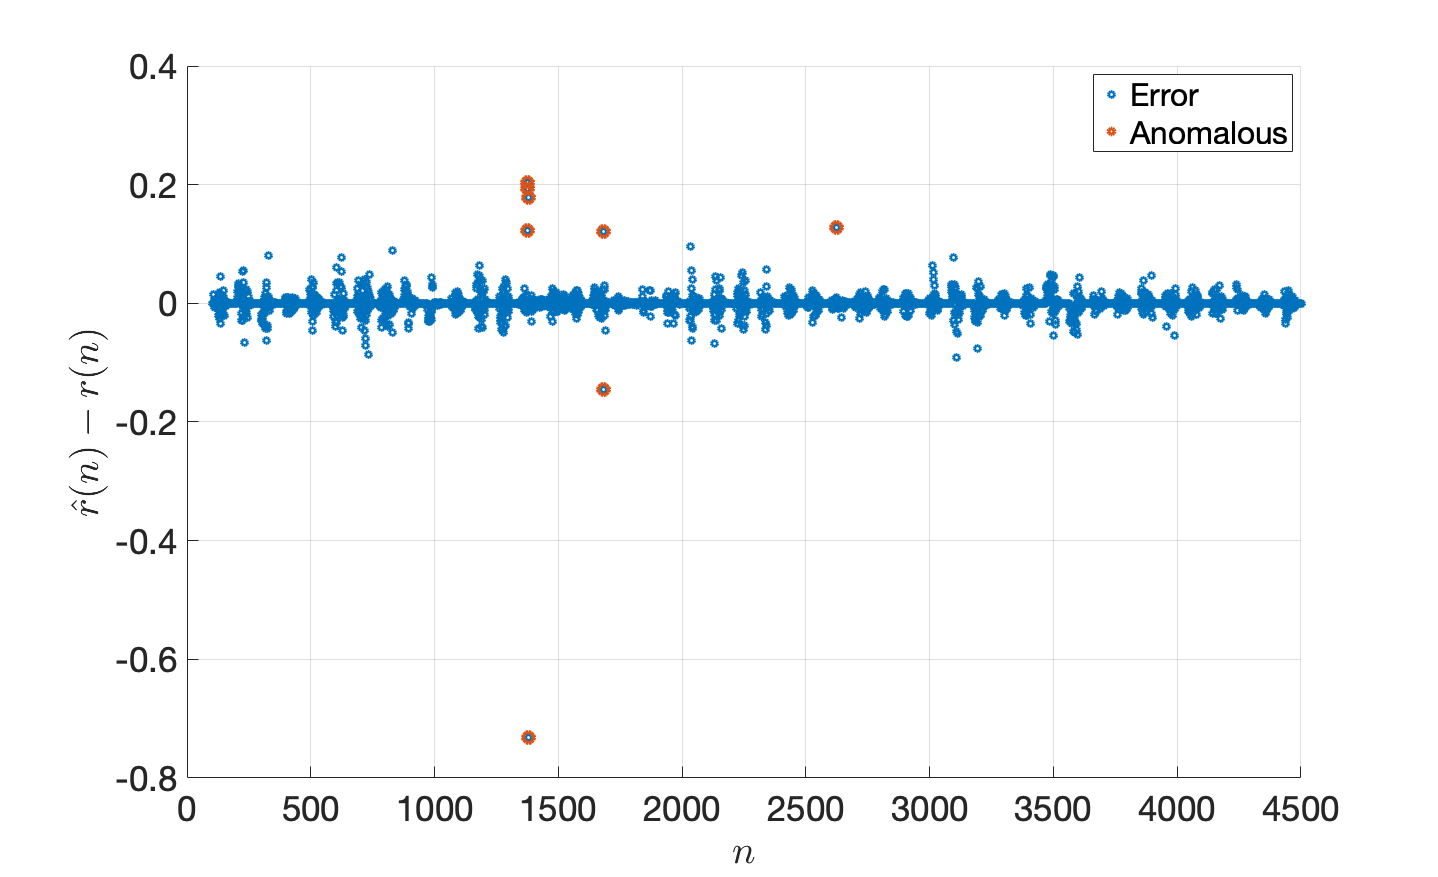


figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
grid on;
xlabel("$n$",'Interpreter','latex');
ylabel("$\hat{r}(n)-r(n)$",'Interpreter','latex');
set(gca,'FontSize',35);
scatter(N+P+1:length(x_test),e_cor,'LineWidth',3);
scatter(N+n_an,e_an,120,'LineWidth',4)
xlim([0 length(x_test)]);
legend("Error","Anomalous");
saveas(gcf,'./figures/R2d_error.png');